# Plots

Laby Nicolas & Van Mechelen Alex

clc, clearvars
set(groot,'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
set(groot,'defaultLegendLocation','best')

# Basic Q-value algorithm

## 1 Example

exploration function = IdentityExplorationMethod

reward = loss*-100 + (number_of_completed_rows+above_row_completion)*500;

**float** gamma = 0.80f;*        // Discount factor*

**float** alpha = 0.02f;*        // Learning rate*

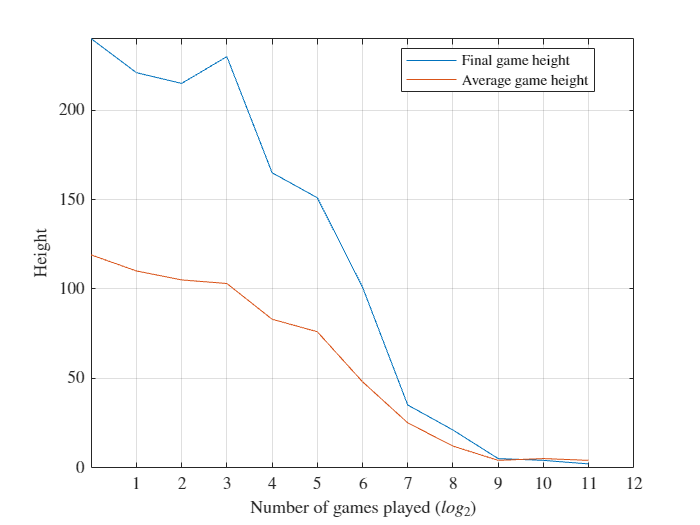

data1 = [1 240 0 767 119
2 221 0 1459 110
4 215 0 2786 105
8 230 0 5204 103
16 165 0 9577 83
32 151 0 16860 76
64 101 0 28223 48
128 35 0 44714 25
256 21 0 66138 12
512 5 0 91211 4
1024 4 0 114578 5
2048 2 0 135171 4];

subplot
plot(log2(data1(:,1)), data1(:,2))
hold on
plot(log2(data1(:,1)), data1(:,5))
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("Height")
xticks(1:12)
axis([0 12 0 max(data1(:,2))])
legend("Final game height", "Average game height")

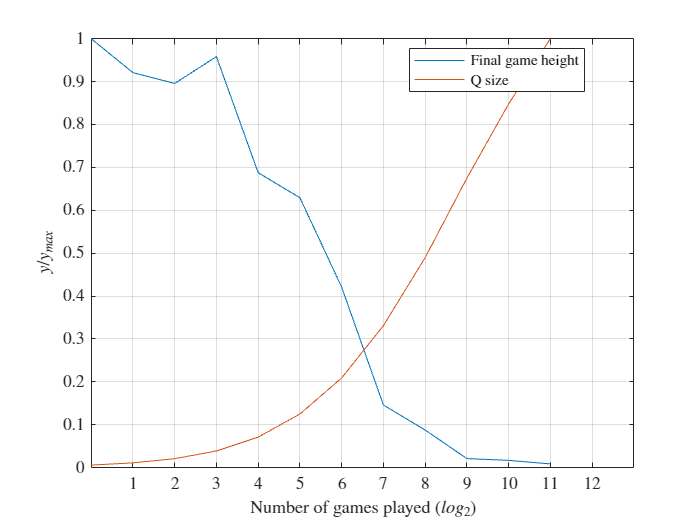


plot(log2(data1(:,1)), data1(:,2)./max(data1(:,2)))
hold on
%plot(log2(data1(:,1)), data1(:,3)./max(data1(:,3)))
plot(log2(data1(:,1)), data1(:,4)./max(data1(:,4)))
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("$y/y_{max}$")
%legend("Final game height", "Epsilon", "Q size")
legend("Final game height", "Q size")
xticks(1:12)
axis([0 13 0 1])

## 2 Play with discount factor and learning rate

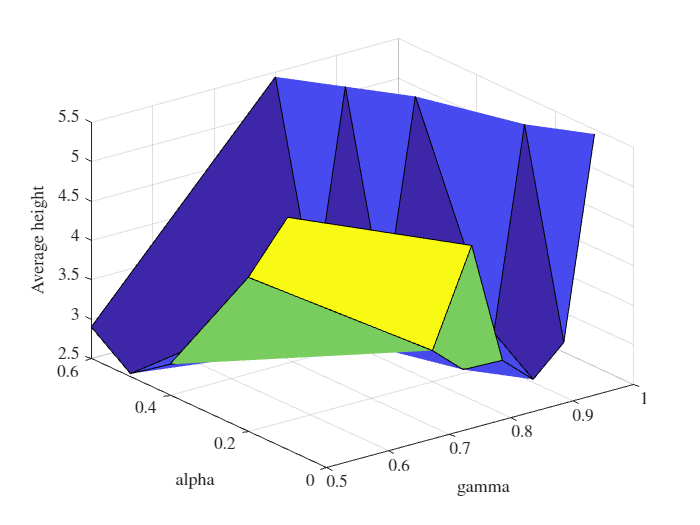

log_data1  = importdata('log_gamma_=0.500000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data2  = importdata('log_gamma_=0.500000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data3  = importdata('log_gamma_=0.500000_alpha_=0.400000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data4  = importdata('log_gamma_=0.500000_alpha_=0.500000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data5  = importdata('log_gamma_=0.500000_alpha_=0.600000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data6  = importdata('log_gamma_=0.800000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data7  = importdata('log_gamma_=0.800000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data8  = importdata('log_gamma_=0.800000_alpha_=0.400000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data9  = importdata('log_gamma_=0.800000_alpha_=0.500000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data10 = importdata('log_gamma_=0.800000_alpha_=0.600000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data11 = importdata('log_gamma_=0.850000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data12 = importdata('log_gamma_=0.850000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data13 = importdata('log_gamma_=0.850000_alpha_=0.400000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data14 = importdata('log_gamma_=0.850000_alpha_=0.500000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data15 = importdata('log_gamma_=0.850000_alpha_=0.600000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data16 = importdata('log_gamma_=0.900000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data17 = importdata('log_gamma_=0.900000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data18 = importdata('log_gamma_=0.900000_alpha_=0.400000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data19 = importdata('log_gamma_=0.900000_alpha_=0.500000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data20 = importdata('log_gamma_=0.900000_alpha_=0.600000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data21 = importdata('log_gamma_=0.950000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data22 = importdata('log_gamma_=0.950000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data23 = importdata('log_gamma_=0.950000_alpha_=0.400000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data24 = importdata('log_gamma_=0.950000_alpha_=0.500000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data25 = importdata('log_gamma_=0.950000_alpha_=0.600000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data26 = importdata('log_gamma_=1.000000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data27 = importdata('log_gamma_=1.000000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data28 = importdata('log_gamma_=1.000000_alpha_=0.400000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data29 = importdata('log_gamma_=1.000000_alpha_=0.500000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data30 = importdata('log_gamma_=1.000000_alpha_=0.600000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;


avgHeight1 = str2double(cell2mat(log_data1(14,5)));
avgHeight2 = str2double(cell2mat(log_data2(14,5)));
avgHeight3 = str2double(cell2mat(log_data3(14,5)));
avgHeight4 = str2double(cell2mat(log_data4(14,5)));
avgHeight5 = str2double(cell2mat(log_data5(14,5))) ;
avgHeight6 = str2double(cell2mat(log_data6(14,5))) ;
avgHeight7 = str2double(cell2mat(log_data7(14,5))) ;
avgHeight8 = str2double(cell2mat(log_data8(14,5))) ;
avgHeight9 = str2double(cell2mat(log_data9(14,5))) ;
avgHeight10 = str2double(cell2mat(log_data10(14,5))) ;
avgHeight11 = str2double(cell2mat(log_data11(14,5))) ;
avgHeight12 = str2double(cell2mat(log_data12(14,5))) ;
avgHeight13 = str2double(cell2mat(log_data13(14,5))) ;
avgHeight14 = str2double(cell2mat(log_data14(14,5))) ;
avgHeight15 = str2double(cell2mat(log_data15(14,5))) ;
avgHeight16 = str2double(cell2mat(log_data16(14,5))) ;
avgHeight17 = str2double(cell2mat(log_data17(14,5))) ;
avgHeight18 = str2double(cell2mat(log_data18(14,5))) ;
avgHeight19 = str2double(cell2mat(log_data19(14,5))) ;
avgHeight20 = str2double(cell2mat(log_data20(14,5))) ;
avgHeight21 = str2double(cell2mat(log_data21(14,5))) ;
avgHeight22 = str2double(cell2mat(log_data22(14,5))) ;
avgHeight23 = str2double(cell2mat(log_data23(14,5))) ;
avgHeight24 = str2double(cell2mat(log_data24(14,5))) ;
avgHeight25 = str2double(cell2mat(log_data25(14,5))) ;
avgHeight26 = str2double(cell2mat(log_data26(14,5))) ;
avgHeight27 = str2double(cell2mat(log_data27(14,5))) ;
avgHeight28 = str2double(cell2mat(log_data28(14,5))) ;
avgHeight29 = str2double(cell2mat(log_data29(14,5))) ;
avgHeight30 = str2double(cell2mat(log_data30(14,5))) ;


x = [0.5 0.8 0.85 0.9 0.95 1];
y = [0.1 0.2 0.4 0.5 0.6];
z = [avgHeight1 avgHeight2 avgHeight3 avgHeight4 avgHeight5 avgHeight6
    avgHeight7 avgHeight8 avgHeight9 avgHeight10 avgHeight11 avgHeight12
    avgHeight13 avgHeight14 avgHeight15 avgHeight16 avgHeight17 avgHeight18
    avgHeight19 avgHeight20 avgHeight21 avgHeight22 avgHeight23 avgHeight24
    avgHeight25 avgHeight26 avgHeight27 avgHeight28 avgHeight29 avgHeight30];

surf(x,y,z)

ylabel("alpha")
xlabel("gamma")
zlabel("Average height")

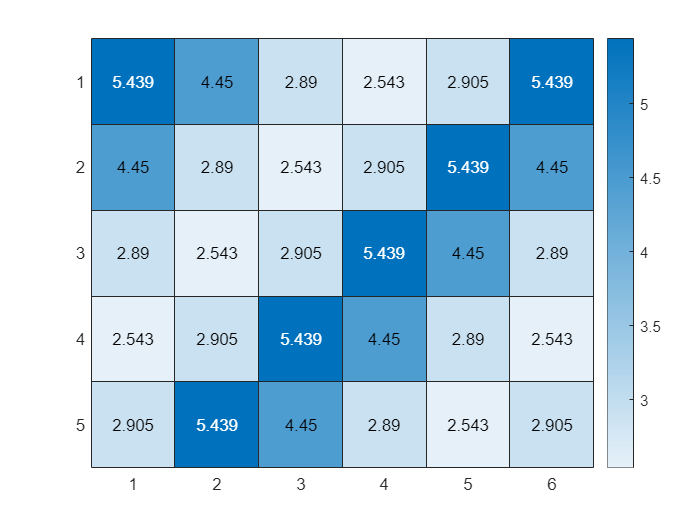

heatmap(z)

v2

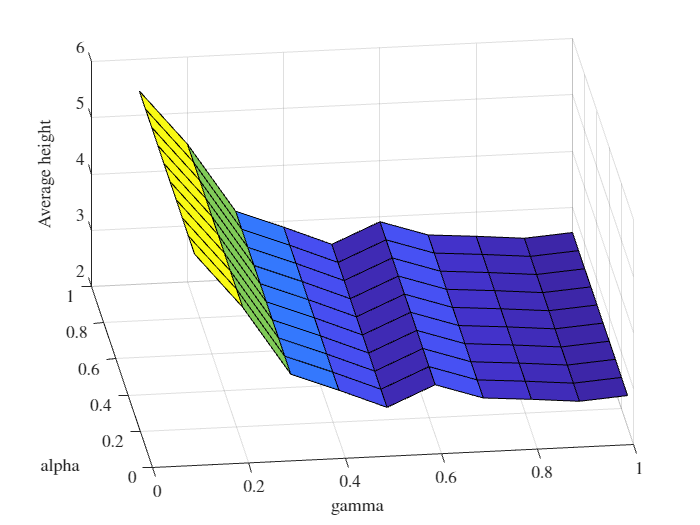

log_data1 = importdata('log_gamma_=0.100000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data2 = importdata('log_gamma_=0.200000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data3 = importdata('log_gamma_=0.300000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data4 = importdata('log_gamma_=0.400000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data5 = importdata('log_gamma_=0.500000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data6 = importdata('log_gamma_=0.600000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data7 = importdata('log_gamma_=0.700000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data8 = importdata('log_gamma_=0.800000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data9 = importdata('log_gamma_=0.900000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data10 = importdata('log_gamma_=1.000000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data11 = importdata('log_gamma_=0.100000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data12 = importdata('log_gamma_=0.200000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data13 = importdata('log_gamma_=0.300000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data14 = importdata('log_gamma_=0.400000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data15 = importdata('log_gamma_=0.500000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data16 = importdata('log_gamma_=0.600000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data17 = importdata('log_gamma_=0.700000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data18 = importdata('log_gamma_=0.800000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data19 = importdata('log_gamma_=0.900000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data20 = importdata('log_gamma_=1.000000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data21 = importdata('log_gamma_=0.100000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data22 = importdata('log_gamma_=0.200000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data23 = importdata('log_gamma_=0.300000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data24 = importdata('log_gamma_=0.400000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data25 = importdata('log_gamma_=0.500000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data26 = importdata('log_gamma_=0.600000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data27 = importdata('log_gamma_=0.700000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data28 = importdata('log_gamma_=0.800000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data29 = importdata('log_gamma_=0.900000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data30 = importdata('log_gamma_=1.000000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data31 = importdata('log_gamma_=0.100000_alpha_=0.400000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data32 = importdata('log_gamma_=0.200000_alpha_=0.400000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data33 = importdata('log_gamma_=0.300000_alpha_=0.400000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data34 = importdata('log_gamma_=0.400000_alpha_=0.400000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data35 = importdata('log_gamma_=0.500000_alpha_=0.400000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data36 = importdata('log_gamma_=0.600000_alpha_=0.400000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data37 = importdata('log_gamma_=0.700000_alpha_=0.400000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data38 = importdata('log_gamma_=0.800000_alpha_=0.400000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data39 = importdata('log_gamma_=0.900000_alpha_=0.400000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data40 = importdata('log_gamma_=1.000000_alpha_=0.400000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data41 = importdata('log_gamma_=0.100000_alpha_=0.500000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data42 = importdata('log_gamma_=0.200000_alpha_=0.500000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data43 = importdata('log_gamma_=0.300000_alpha_=0.500000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data44 = importdata('log_gamma_=0.400000_alpha_=0.500000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data45 = importdata('log_gamma_=0.500000_alpha_=0.500000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data46 = importdata('log_gamma_=0.600000_alpha_=0.500000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data47 = importdata('log_gamma_=0.700000_alpha_=0.500000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data48 = importdata('log_gamma_=0.800000_alpha_=0.500000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data49 = importdata('log_gamma_=0.900000_alpha_=0.500000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data50 = importdata('log_gamma_=1.000000_alpha_=0.500000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data51 = importdata('log_gamma_=0.100000_alpha_=0.600000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data52 = importdata('log_gamma_=0.200000_alpha_=0.600000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data53 = importdata('log_gamma_=0.300000_alpha_=0.600000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data54 = importdata('log_gamma_=0.400000_alpha_=0.600000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data55 = importdata('log_gamma_=0.500000_alpha_=0.600000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data56 = importdata('log_gamma_=0.600000_alpha_=0.600000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data57 = importdata('log_gamma_=0.700000_alpha_=0.600000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data58 = importdata('log_gamma_=0.800000_alpha_=0.600000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data59 = importdata('log_gamma_=0.900000_alpha_=0.600000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data60 = importdata('log_gamma_=1.000000_alpha_=0.600000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data61 = importdata('log_gamma_=0.100000_alpha_=0.700000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data62 = importdata('log_gamma_=0.200000_alpha_=0.700000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data63 = importdata('log_gamma_=0.300000_alpha_=0.700000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data64 = importdata('log_gamma_=0.400000_alpha_=0.700000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data65 = importdata('log_gamma_=0.500000_alpha_=0.700000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data66 = importdata('log_gamma_=0.600000_alpha_=0.700000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data67 = importdata('log_gamma_=0.700000_alpha_=0.700000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data68 = importdata('log_gamma_=0.800000_alpha_=0.700000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data69 = importdata('log_gamma_=0.900000_alpha_=0.700000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data70 = importdata('log_gamma_=1.000000_alpha_=0.700000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data71 = importdata('log_gamma_=0.100000_alpha_=0.800000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data72 = importdata('log_gamma_=0.200000_alpha_=0.800000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data73 = importdata('log_gamma_=0.300000_alpha_=0.800000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data74 = importdata('log_gamma_=0.400000_alpha_=0.800000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data75 = importdata('log_gamma_=0.500000_alpha_=0.800000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data76 = importdata('log_gamma_=0.600000_alpha_=0.800000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data77 = importdata('log_gamma_=0.700000_alpha_=0.800000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data78 = importdata('log_gamma_=0.800000_alpha_=0.800000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data79 = importdata('log_gamma_=0.900000_alpha_=0.800000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data80 = importdata('log_gamma_=1.000000_alpha_=0.800000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data81 = importdata('log_gamma_=0.100000_alpha_=0.900000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data82 = importdata('log_gamma_=0.200000_alpha_=0.900000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data83 = importdata('log_gamma_=0.300000_alpha_=0.900000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data84 = importdata('log_gamma_=0.400000_alpha_=0.900000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data85 = importdata('log_gamma_=0.500000_alpha_=0.900000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data86 = importdata('log_gamma_=0.600000_alpha_=0.900000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data87 = importdata('log_gamma_=0.700000_alpha_=0.900000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data88 = importdata('log_gamma_=0.800000_alpha_=0.900000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data89 = importdata('log_gamma_=0.900000_alpha_=0.900000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data90 = importdata('log_gamma_=1.000000_alpha_=0.900000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data91 = importdata('log_gamma_=0.100000_alpha_=1.000000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data92 = importdata('log_gamma_=0.200000_alpha_=1.000000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data93 = importdata('log_gamma_=0.300000_alpha_=1.000000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data94 = importdata('log_gamma_=0.400000_alpha_=1.000000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data95 = importdata('log_gamma_=0.500000_alpha_=1.000000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data96 = importdata('log_gamma_=0.600000_alpha_=1.000000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data97 = importdata('log_gamma_=0.700000_alpha_=1.000000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data98 = importdata('log_gamma_=0.800000_alpha_=1.000000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data99 = importdata('log_gamma_=0.900000_alpha_=1.000000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;
log_data100 = importdata('log_gamma_=1.000000_alpha_=1.000000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt').textdata;

avgHeight1 = str2double(cell2mat(log_data1(14, 5)));
avgHeight2 = str2double(cell2mat(log_data2(14, 5)));
avgHeight3 = str2double(cell2mat(log_data3(14, 5)));
avgHeight4 = str2double(cell2mat(log_data4(14, 5)));
avgHeight5 = str2double(cell2mat(log_data5(14, 5)));
avgHeight6 = str2double(cell2mat(log_data6(14, 5)));
avgHeight7 = str2double(cell2mat(log_data7(14, 5)));
avgHeight8 = str2double(cell2mat(log_data8(14, 5)));
avgHeight9 = str2double(cell2mat(log_data9(14, 5)));
avgHeight10 = str2double(cell2mat(log_data10(14, 5)));
avgHeight11 = str2double(cell2mat(log_data11(14, 5)));
avgHeight12 = str2double(cell2mat(log_data12(14, 5)));
avgHeight13 = str2double(cell2mat(log_data13(14, 5)));
avgHeight14 = str2double(cell2mat(log_data14(14, 5)));
avgHeight15 = str2double(cell2mat(log_data15(14, 5)));
avgHeight16 = str2double(cell2mat(log_data16(14, 5)));
avgHeight17 = str2double(cell2mat(log_data17(14, 5)));
avgHeight18 = str2double(cell2mat(log_data18(14, 5)));
avgHeight19 = str2double(cell2mat(log_data19(14, 5)));
avgHeight20 = str2double(cell2mat(log_data20(14, 5)));
avgHeight21 = str2double(cell2mat(log_data21(14, 5)));
avgHeight22 = str2double(cell2mat(log_data22(14, 5)));
avgHeight23 = str2double(cell2mat(log_data23(14, 5)));
avgHeight24 = str2double(cell2mat(log_data24(14, 5)));
avgHeight25 = str2double(cell2mat(log_data25(14, 5)));
avgHeight26 = str2double(cell2mat(log_data26(14, 5)));
avgHeight27 = str2double(cell2mat(log_data27(14, 5)));
avgHeight28 = str2double(cell2mat(log_data28(14, 5)));
avgHeight29 = str2double(cell2mat(log_data29(14, 5)));
avgHeight30 = str2double(cell2mat(log_data30(14, 5)));
avgHeight31 = str2double(cell2mat(log_data31(14, 5)));
avgHeight32 = str2double(cell2mat(log_data32(14, 5)));
avgHeight33 = str2double(cell2mat(log_data33(14, 5)));
avgHeight34 = str2double(cell2mat(log_data34(14, 5)));
avgHeight35 = str2double(cell2mat(log_data35(14, 5)));
avgHeight36 = str2double(cell2mat(log_data36(14, 5)));
avgHeight37 = str2double(cell2mat(log_data37(14, 5)));
avgHeight38 = str2double(cell2mat(log_data38(14, 5)));
avgHeight39 = str2double(cell2mat(log_data39(14, 5)));
avgHeight40 = str2double(cell2mat(log_data40(14, 5)));
avgHeight41 = str2double(cell2mat(log_data41(14, 5)));
avgHeight42 = str2double(cell2mat(log_data42(14, 5)));
avgHeight43 = str2double(cell2mat(log_data43(14, 5)));
avgHeight44 = str2double(cell2mat(log_data44(14, 5)));
avgHeight45 = str2double(cell2mat(log_data45(14, 5)));
avgHeight46 = str2double(cell2mat(log_data46(14, 5)));
avgHeight47 = str2double(cell2mat(log_data47(14, 5)));
avgHeight48 = str2double(cell2mat(log_data48(14, 5)));
avgHeight49 = str2double(cell2mat(log_data49(14, 5)));
avgHeight50 = str2double(cell2mat(log_data50(14, 5)));
avgHeight51 = str2double(cell2mat(log_data51(14, 5)));
avgHeight52 = str2double(cell2mat(log_data52(14, 5)));
avgHeight53 = str2double(cell2mat(log_data53(14, 5)));
avgHeight54 = str2double(cell2mat(log_data54(14, 5)));
avgHeight55 = str2double(cell2mat(log_data55(14, 5)));
avgHeight56 = str2double(cell2mat(log_data56(14, 5)));
avgHeight57 = str2double(cell2mat(log_data57(14, 5)));
avgHeight58 = str2double(cell2mat(log_data58(14, 5)));
avgHeight59 = str2double(cell2mat(log_data59(14, 5)));
avgHeight60 = str2double(cell2mat(log_data60(14, 5)));
avgHeight61 = str2double(cell2mat(log_data61(14, 5)));
avgHeight62 = str2double(cell2mat(log_data62(14, 5)));
avgHeight63 = str2double(cell2mat(log_data63(14, 5)));
avgHeight64 = str2double(cell2mat(log_data64(14, 5)));
avgHeight65 = str2double(cell2mat(log_data65(14, 5)));
avgHeight66 = str2double(cell2mat(log_data66(14, 5)));
avgHeight67 = str2double(cell2mat(log_data67(14, 5)));
avgHeight68 = str2double(cell2mat(log_data68(14, 5)));
avgHeight69 = str2double(cell2mat(log_data69(14, 5)));
avgHeight70 = str2double(cell2mat(log_data70(14, 5)));
avgHeight71 = str2double(cell2mat(log_data71(14, 5)));
avgHeight72 = str2double(cell2mat(log_data72(14, 5)));
avgHeight73 = str2double(cell2mat(log_data73(14, 5)));
avgHeight74 = str2double(cell2mat(log_data74(14, 5)));
avgHeight75 = str2double(cell2mat(log_data75(14, 5)));
avgHeight76 = str2double(cell2mat(log_data76(14, 5)));
avgHeight77 = str2double(cell2mat(log_data77(14, 5)));
avgHeight78 = str2double(cell2mat(log_data78(14, 5)));
avgHeight79 = str2double(cell2mat(log_data79(14, 5)));
avgHeight80 = str2double(cell2mat(log_data80(14, 5)));
avgHeight81 = str2double(cell2mat(log_data81(14, 5)));
avgHeight82 = str2double(cell2mat(log_data82(14, 5)));
avgHeight83 = str2double(cell2mat(log_data83(14, 5)));
avgHeight84 = str2double(cell2mat(log_data84(14, 5)));
avgHeight85 = str2double(cell2mat(log_data85(14, 5)));
avgHeight86 = str2double(cell2mat(log_data86(14, 5)));
avgHeight87 = str2double(cell2mat(log_data87(14, 5)));
avgHeight88 = str2double(cell2mat(log_data88(14, 5)));
avgHeight89 = str2double(cell2mat(log_data89(14, 5)));
avgHeight90 = str2double(cell2mat(log_data90(14, 5)));
avgHeight91 = str2double(cell2mat(log_data91(14, 5)));
avgHeight92 = str2double(cell2mat(log_data92(14, 5)));
avgHeight93 = str2double(cell2mat(log_data93(14, 5)));
avgHeight94 = str2double(cell2mat(log_data94(14, 5)));
avgHeight95 = str2double(cell2mat(log_data95(14, 5)));
avgHeight96 = str2double(cell2mat(log_data96(14, 5)));
avgHeight97 = str2double(cell2mat(log_data97(14, 5)));
avgHeight98 = str2double(cell2mat(log_data98(14, 5)));
avgHeight99 = str2double(cell2mat(log_data99(14, 5)));
avgHeight100 = str2double(cell2mat(log_data100(14, 5)));

x = [0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1];
y = [0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1];

z = [avgHeight1 avgHeight2 avgHeight3 avgHeight4 avgHeight5 avgHeight6 avgHeight7 avgHeight8 avgHeight9 avgHeight10
    avgHeight11 avgHeight12 avgHeight13 avgHeight14 avgHeight15 avgHeight16 avgHeight17 avgHeight18 avgHeight19 avgHeight20
    avgHeight21 avgHeight22 avgHeight23 avgHeight24 avgHeight25 avgHeight26 avgHeight27 avgHeight28 avgHeight29 avgHeight30
    avgHeight31 avgHeight32 avgHeight33 avgHeight34 avgHeight35 avgHeight36 avgHeight37 avgHeight38 avgHeight39 avgHeight40
    avgHeight41 avgHeight42 avgHeight43 avgHeight44 avgHeight45 avgHeight46 avgHeight47 avgHeight48 avgHeight49 avgHeight50
    avgHeight51 avgHeight52 avgHeight53 avgHeight54 avgHeight55 avgHeight56 avgHeight57 avgHeight58 avgHeight59 avgHeight60
    avgHeight61 avgHeight62 avgHeight63 avgHeight64 avgHeight65 avgHeight66 avgHeight67 avgHeight68 avgHeight69 avgHeight70
    avgHeight71 avgHeight72 avgHeight73 avgHeight74 avgHeight75 avgHeight76 avgHeight77 avgHeight78 avgHeight79 avgHeight80
    avgHeight81 avgHeight82 avgHeight83 avgHeight84 avgHeight85 avgHeight86 avgHeight87 avgHeight88 avgHeight89 avgHeight90
    avgHeight91 avgHeight92 avgHeight93 avgHeight94 avgHeight95 avgHeight96 avgHeight97 avgHeight98 avgHeight99 avgHeight100];

surf(x,y,z')

ylabel("alpha")
xlabel("gamma")
zlabel("Average height")

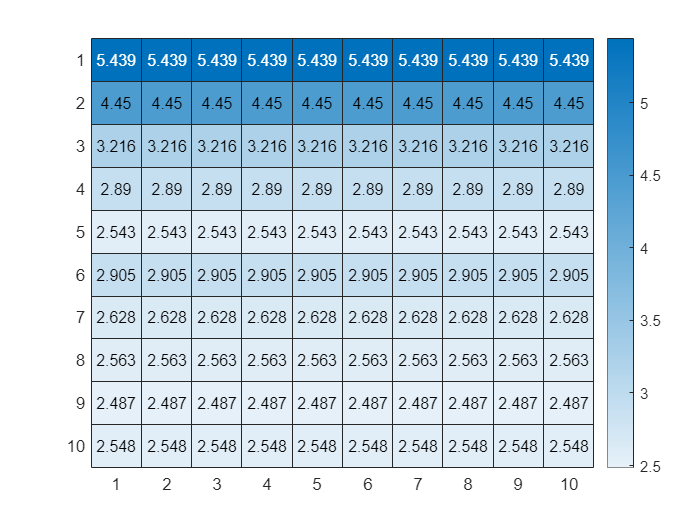


heatmap(z)

## 3 Play with reward function

The following metrics are used to calculate the reward function:

- loss (*Number of rows added to height when they're 'pushed down')*

- completed rows (number_of_completed_rows+above_row_completion)

- hole density

- bumpiness

reward = k_loss*loss + k_comp*(number_of_completed_rows+above_row_completion)

Everytime we can play with the coefficients associated to a metric

### 1 Play with loss & completed rows

The final metric will be the final/lowest height achieved after 2^11 games (not 2^13 for computation reasons)

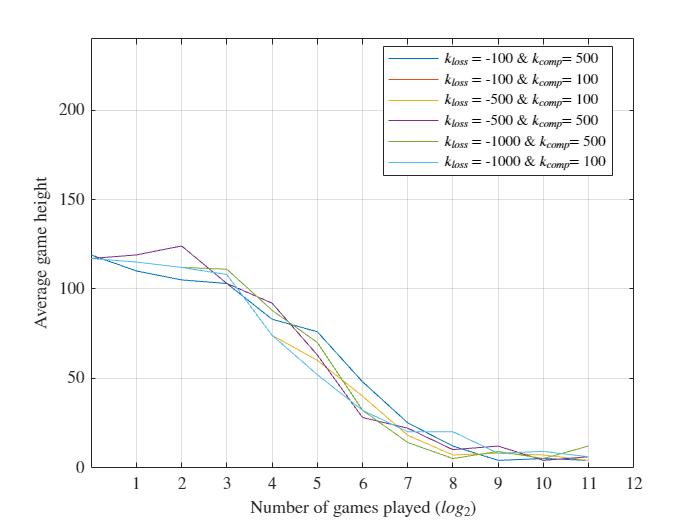

data1 = [1 240 0 767 119
2 221 0 1459 110
4 215 0 2786 105
8 230 0 5204 103
16 165 0 9577 83
32 151 0 16860 76
64 101 0 28223 48
128 35 0 44714 25
256 21 0 66138 12
512 5 0 91211 4
1024 4 0 114578 5
2048 2 0 135171 4]; % k_loss = -100 & k_comp = 500

data2 = [1 234 0 749 117
2 234 0 1456 119
4 256 0 2784 124
8 195 0 5214 103
16 187 0 9597 92
32 138 0 16945 63
64 46 0 28378 28
128 44 0 45087 22
256 14 0 66362 10
512 22 0 91248 12
1024 2 0 114415 4
2048 5 0 135733 6]; % k_loss = -100 & k_comp = 100

data3 = [1 234 0 771 117
2 233 0 1492 115
4 226 0 2818 112
8 209 0 5303 108
16 155 0 9735 74
32 120 0 17081 60
64 83 0 28579 40
128 51 0 45085 18
256 10 0 66538 7
512 13 0 91651 8
1024 10 0 114908 7
2048 8 0 135470 4
]; % k_loss = -500 & k_comp = 100

data4 = [1 234 0 749 117
2 234 0 1456 119
4 256 0 2784 124
8 195 0 5214 103
16 187 0 9597 92
32 138 0 16945 63
64 46 0 28378 28
128 44 0 45087 22
256 14 0 66362 10
512 22 0 91248 12
1024 2 0 114415 4
2048 5 0 135733 6]; % k_loss = -500 & k_comp = 500

data5 = [1 234 0 771 117
2 233 0 1492 115
4 226 0 2818 112
8 220 0 5322 111
16 169 0 9759 88
32 147 0 17163 70
64 68 0 28687 32
128 27 0 45292 14
256 11 0 66763 5
512 9 0 91922 9
1024 5 0 115040 5
2048 14 0 135846 12]; % k_loss = -1000 & k_comp = 500

data6 = [1 234 0 771 117
2 233 0 1492 115
4 226 0 2818 112
8 209 0 5303 108
16 155 0 9735 74
32 102 0 17025 52
64 76 0 28613 32
128 23 0 45113 20
256 22 0 66161 20
512 11 0 91229 8
1024 23 0 114497 9
2048 4 0 135744 6]; % k_loss = -1000 & k_comp = 100

data = zeros(12,5,2);
data(:,:,1) = data1;
data(:,:,2) = data2;
data(:,:,3) = data3;
data(:,:,4) = data4;
data(:,:,5) = data5;
data(:,:,6) = data6;

subplot
for i = 1:size(data,3)
    plot(log2(data(:,1,i)), data(:,5,i))
    hold on
end
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("Average game height")
xticks(1:12)
axis([0 12 0 max(data1(:,2))])
legend("$k_{loss}$ = -100 \& $k_{comp}$= 500", ...
    "$k_{loss}$ = -100 \& $k_{comp}$= 100", ...
    "$k_{loss}$ = -500 \& $k_{comp}$= 100", ...
    "$k_{loss}$ = -500 \& $k_{comp}$= 500", ...
    "$k_{loss}$ = -1000 \& $k_{comp}$= 500", ...
    "$k_{loss}$ = -1000 \& $k_{comp}$= 100")

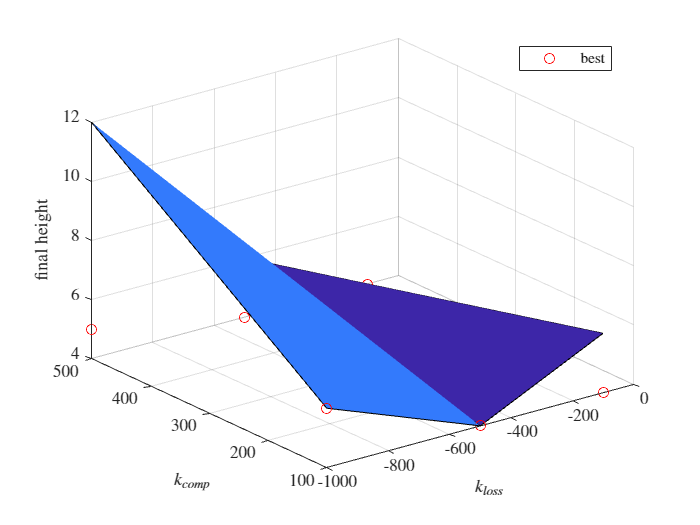


x3 = [-1000 -500 -100];
y3 = [100 500];
z3 = [data6(end,5) data3(end,5) data2(end,5); data5(end,5) data4(end,5) data1(end,5)];
%z2 = [min(data3(:,2)) min(data2(:,2)); min(data4(:,2)) min(data1(:,2))];
x2 = [-100 -100 -500 -500 -1000 -1000];
y2 = [500 100 100 500 500 100];
z2 = [min(data1(:,5)) min(data2(:,5)) min(data3(:,5)) min(data4(:,5)), min(data5(:,5)), min(data6(:,5))];
surf(x3,y3,z3)
hold on
plot3(x2,y2,z2, 'ro')
hold off
xlabel("$k_{loss}$")
ylabel("$k_{comp}$")
zlabel("final height")
legend("", "best")

### 2 Play with hole density & bumpiness

(...)

## 4 Performance metric

Final height vs evolution during the game

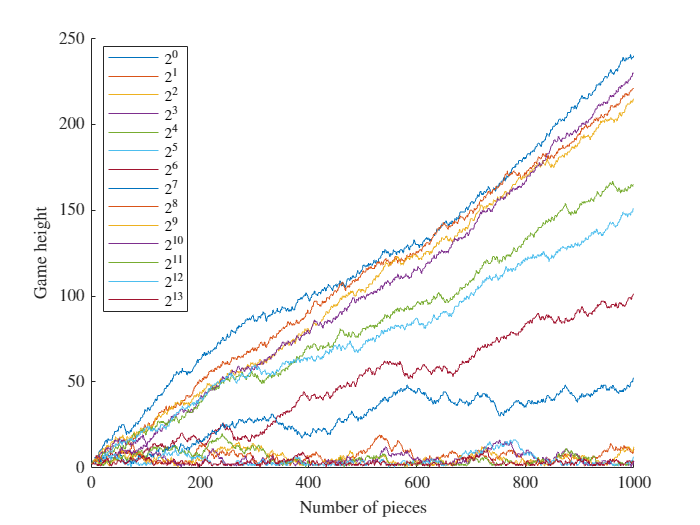

% load heights.txt
log_data = importdata('heights.txt');

figure
hold on
legend_str = cell(1, ceil(log2(size(log_data, 1))));
for i = 1:size(log_data, 1)
    if ~bitand(i, i-1) %if a power of two
        max_i = i;
        plot(1:length(log_data(i,:)),log_data(i,:))
        legend_str{log2(i)+1} = ['$2^{' num2str(log2(i)) '}$'];
    end
end
hold off

legend(legend_str(~cellfun('isempty',legend_str)))
xlabel('Number of pieces')
ylabel('Game height')

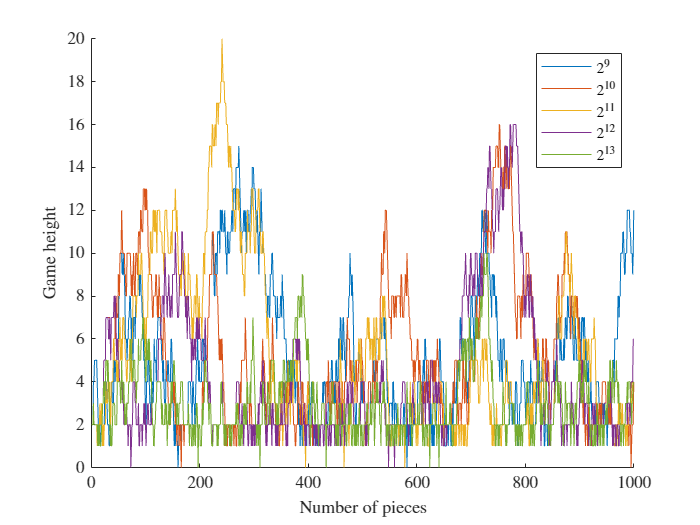


% mean and variance

mean_data = zeros(max_i,1);
var_data= zeros(max_i,1);

for i = 1:size(log_data, 1)
    mean_data(i) = mean(log_data(i,:));
    var_data(i) = var(log_data(i,:));
end

%last 5 powers of 2

figure
hold on
legend_str = cell(1, ceil(log2(size(log_data, 1))));
for i = 1:size(log_data, 1)
    if ~bitand(i, i-1) && i>2^(13-5) %if a power of two
        plot(1:length(log_data(i,:)),log_data(i,:))
        legend_str{log2(i)+1} = ['$2^{' num2str(log2(i)) '}$'];
    end
end
hold off

legend(legend_str(~cellfun('isempty',legend_str)))
xlabel('Number of pieces')
ylabel('Game height')

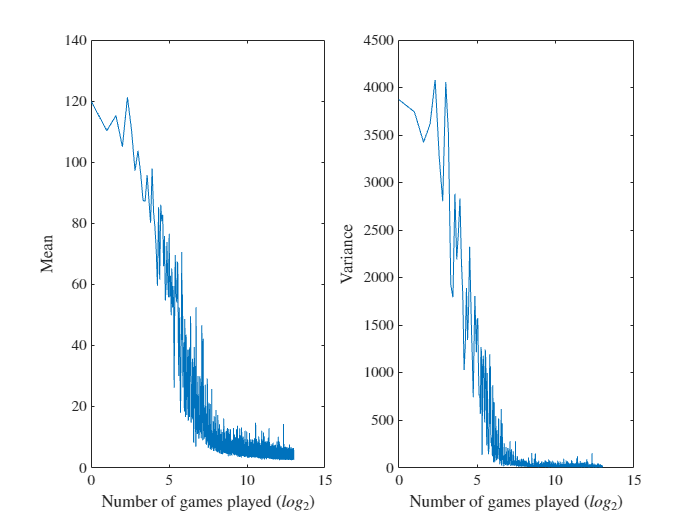


% hold on
% for i = 1:size(log_data, 1)
%     if ~bitand(i, i-1) && i>2^(13-5) %if a power of two
%         plot([1 length(log_data(i,:))], [mean_data(i) mean_data(i)], '--')
%     end
% end
% hold off

% plot((1:size(log_data, 1)), mean_data)
% ylabel("Mean")
% xlabel("Number of games played")
% 
% plot((1:size(log_data, 1)), var_data)
% ylabel("Variance")
% xlabel("Number of games played")

subplot(1,2,1)
plot(log2(1:size(log_data, 1)), mean_data)
ylabel("Mean")
xlabel("Number of games played ($log_2$)")
subplot(1,2,2)
plot(log2(1:size(log_data, 1)), var_data)
xlabel("Number of games played ($log_2$)")
ylabel("Variance")

# Discussion over the exploration method

For the following discussion we will always use the following cost function and parameters:

reward = loss*-100 + (number_of_completed_rows+above_row_completion)*500;

**float** gamma = 0.80f;*        // Discount factor*

**float** alpha = 0.02f;*        // Learning rate*

## 1 Random exploration method

exploration function = RandomExplorationMethod

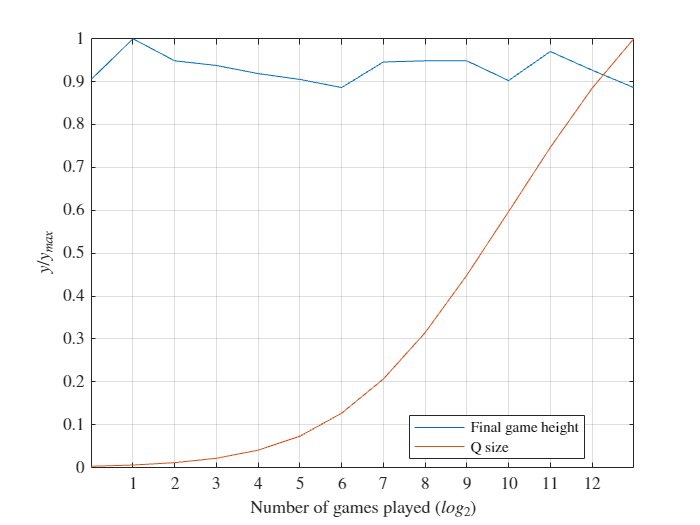

data1 = [1, 334, 0, 803
2, 369, 0, 1595
4, 350, 0, 3137
8, 346, 0, 5979
16, 339, 0, 11252
32, 334, 0, 20314
64, 327, 0, 35218
128, 349, 0, 57371
256, 350, 0, 87427
512, 350, 0, 124718
1024, 333, 0, 165909
2048, 358, 0, 207577
4096, 342, 0, 245911
8192, 327, 0, 278052];

figure
plot(log2(data1(:,1)), data1(:,2)./max(data1(:,2)))
hold on
%plot(log2(data1(:,1)), data1(:,3)./max(data1(:,3)))
plot(log2(data1(:,1)), data1(:,4)./max(data1(:,4)))
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("$y/y_{max}$")
%legend("Final game height", "Epsilon", "Q size")
legend("Final game height", "Q size")
xticks(1:12)
axis([0 13 0 1])

## 2 Epsilon greedy exploration method

### 1 Basic

epsilon = 0.1 and no decay

data1 = [];

plot(log2(data1(:,1)), data1(:,2)./max(data1(:,2)))

Index in position 2 exceeds array bounds.

hold on
plot(log2(data1(:,1)), data1(:,3)./max(data1(:,3)))
plot(log2(data1(:,1)), data1(:,4)./max(data1(:,4)))
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("$y/y_{max}$")
legend("Final game height", "Epsilon", "Q size")


### 2 Play with epsilon

epsilon = 0:0.1:0.9 and no decay

data1 = [];

plot(log2(data1(:,1)), data1(:,2)./max(data1(:,2)))
hold on
plot(log2(data1(:,1)), data1(:,3)./max(data1(:,3)))
plot(log2(data1(:,1)), data1(:,4)./max(data1(:,4)))
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("$y/y_{max}$")
legend("Final game height", "Epsilon", "Q size")


### 3 Play with decay

epsilon = 0.1 and decay 

`if`` (``EPSILON` `>` `0.001``) ``EPSILON` `*=` `0.99``; ``else` `EPSILON` `=` `0`

data1 = [1 250 0.1 800 122
2 250 0.099 1499 125
4 250 0.0970299 2855 128
8 241 0.0932065 5384 119
16 184 0.0860058 9841 92
32 125 0.0732303 17474 61
64 128 0.0530906 29537 70
128 33 0.0279042 46983 19
256 36 0.00770858 69435 13
512 7 0 94554 5
1024 11 0 117495 4
2048 2 0 137197 4
4096 4 0 154878 3
8192 9 0 169316 4];

plot(log2(data1(:,1)), data1(:,2)./max(data1(:,2)))
hold on
plot(log2(data1(:,1)), data1(:,3)./max(data1(:,3)))
plot(log2(data1(:,1)), data1(:,4)./max(data1(:,4)))
plot(log2(data1(:,1)), data1(:,5)./max(data1(:,5)))
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("$y/y_{max}$")
legend("Final game height", "Epsilon", "Q size", "Average game height")

## 3 Simple exploration method

### 1 Basic

 **int** N_MAX = 10;

 **double** R_PLUS = 20.0;

data1 = [];

plot(log2(data1(:,1)), data1(:,2)./max(data1(:,2)))
hold on
plot(log2(data1(:,1)), data1(:,3)./max(data1(:,3)))
plot(log2(data1(:,1)), data1(:,4)./max(data1(:,4)))
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("$y/y_{max}$")
legend("Final game height", "Epsilon", "Q size")

### 2 Play with Nmax & Rplus

(...)

# Computing time, convergence rate, stability, ...

(...)